CPR_st.name='CPR';
CPR_st.lat=18.3810653687;
CPR_st.lon=-65.6177520752;
CPR_st.alt=65;
CPR_st.env='coast';
CPR_st.footp='F';

addpath(genpath('M:/pay-prod/Aerosol_actris_trend/'));
CPR_rd=read_betsy('cpr_2004_2018',CPR_st.name);

namesok=fieldnames(CPR_rd);
CT= startsWith(namesok,["T"; "P";"U"]) & contains(namesok,'_');
namesCT=namesok(CT);
for i=1:length(namesCT)
    ind=CPR_rd.(namesCT{i})==99999.999;
CPR_rd.(namesCT{i})(ind)=NaN;
end

datevec(CPR_rd.Time(1))

ans =         2004          10          27           0           0           0


datevec(CPR_rd.Time(end))

ans =         2018           6          13           0           0           0


prctile(CPR_rd.U_S,[5 50 95])

Unrecognized table variable name 'U_S'.

prctile(CPR_rd.U0_S,[5 50 95])
prctile(CPR_rd.U1_S,[5 50 95])
plotFigControl(CPR_rd, CPR_st.name);
% 2 size cut, ok
% sc: ok, max in summer, no negatives

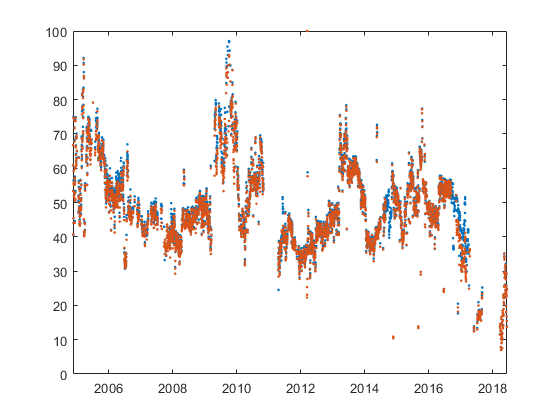

%%
    
figure
plot(CPR_rd.Time,CPR_rd.U0_S,'.');
hold on;
plot(CPR_rd.Time,CPR_rd.U1_S,'.');
plot(CPR_rd.Time,CPR_rd.U_S,'.');

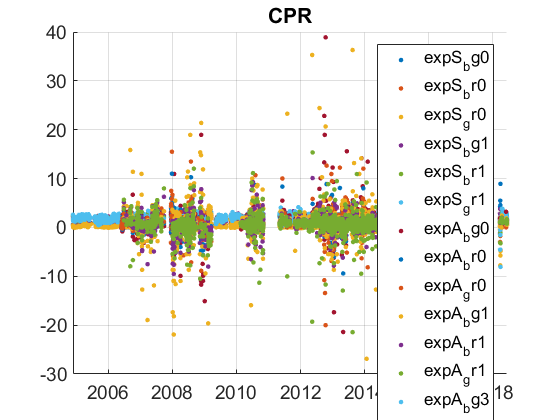

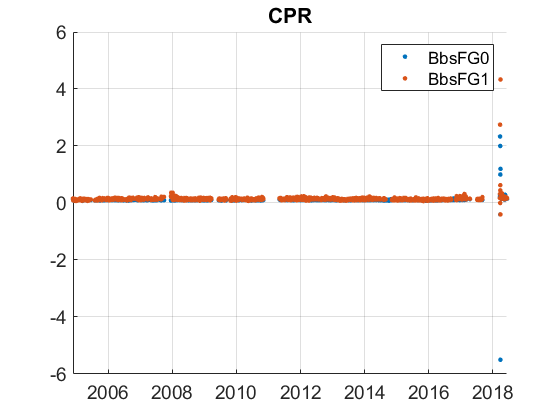

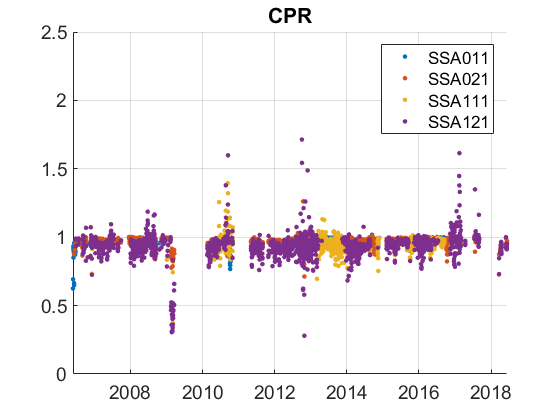

lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;530;660]*ones(1,4);
lambdaAE7=[370 470 520 590 660 880 950];
CPR_cal=compute_exp_SSA(CPR_rd,lambdaSC, lambdaAE);
plotFigControl_cal(CPR_cal, CPR_st.name);

%Questions:
%problems:


% RH: why there is very large variation of RH but no seasonality ?
% why 2018 is not complete ? is it possible to have the whole year ?

% scattering: 2018 data too low: is there any problem ?
%scat: PM1: are the very low value at the end of 2007- begin 2008 and at the end of 2016-begin 2017 real or outliers ?
% scat: too high minima of the ratio of the scattering coefficient and of the exponent for all wavelength pairs in 2008 and for GR in 2013. Do you have an explanation?
%backscattering fraction: very large variation from year to year. Any explanation? is it bounded to the humidity ?

% SSA: the variation are very high and also seems to depends on period and perhaps on humidity. What is your opinion ?

CPR_tr=CPR_rd;
CPR_tr.y=year(CPR_tr.Time);
% begin at the beginning of a year: 2005
%end 2016 due to hurrican
P=timerange('2005-01-01','2017-01-01');
CPR_tr=CPR_tr(P,:);
%RH<50%: a lot of data missing, no clear seasonality but depends on period. For example all 2009 with RH too high
% %U >50% s --> trend in U and dry
names=fieldnames(CPR_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_";"N";"U_S";"U1"]);
N=names(c);
for i=1:length(N)
    CPR_tr.(N{i})=[];
end


%nothing in BaB, BaG and BaR:to delete
CPR_tr.BaB_A=[];
CPR_tr.BaG_A=[];
CPR_tr.BaR_A=[];
%abs: start year=2007
P=timerange('2005-01-01','2006-01-01');
names=fieldnames(CPR_tr);
c= startsWith(names,'Ba');
N=names(c);
for i=1:length(N)
    CPR_tr.(N{i})(P)=NaN;
end
%abs: quite a lot of holes until 2011 ? 

CPR_cal2=compute_exp_SSA(CPR_tr,lambdaSC, lambdaAE);
% absG is longer than absR --> compute SSA with green scat and abs
CPR_cal2.SSA0G=CPR_tr.BsG0_S./(CPR_tr.BsG0_S+CPR_tr.BaG0_A);
CPR_cal2.SSA1G=CPR_tr.BsG1_S./(CPR_tr.BsG1_S+CPR_tr.BaG1_A);
CPR_cal2.SSA0G_dry=CPR_tr.BsG0_S_dry./(CPR_tr.BsG0_S_dry+CPR_tr.BaG0_A);
CPR_cal2.SSA1G_dry=CPR_tr.BsG1_S_dry./(CPR_tr.BsG1_S_dry+CPR_tr.BaG1_A);
CPR_cal2.expS_bg0_dry=real(-log(CPR_tr.BsB0_S_dry./CPR_tr.BsG0_S_dry)/log(lambdaSC(1)/lambdaSC(2)));
CPR_cal2.BbsFG0_dry=CPR_tr.BbsG0_S_dry./CPR_tr.BsG0_S_dry;
CPR_cal2.expS_bg1_dry=real(-log(CPR_tr.BsB1_S_dry./CPR_tr.BsG1_S_dry)/log(lambdaSC(1)/lambdaSC(2)));
CPR_cal2.BbsFG1_dry=CPR_tr.BbsG1_S_dry./CPR_tr.BsG1_S_dry;
%plotFigControl_cal(CPR_cal2,CPR_st.name);
CPR_tr=outerjoin(CPR_tr, CPR_cal2);

%compute trends only on G
CPR_tr.BsB0_S=[];
CPR_tr.BsB1_S=[];
CPR_tr.BsR0_S=[];
CPR_tr.BsR1_S=[];
CPR_tr.BbsB0_S=[];
CPR_tr.BbsB1_S=[];
CPR_tr.BbsR0_S=[];
CPR_tr.BbsR1_S=[];

CPR_tr.BsB0_S_dry=[];
CPR_tr.BsB1_S_dry=[];
CPR_tr.BsR0_S_dry=[];
CPR_tr.BsR1_S_dry=[];
CPR_tr.BbsB0_S_dry=[];
CPR_tr.BbsB1_S_dry=[];
CPR_tr.BbsR0_S_dry=[];
CPR_tr.BbsR1_S_dry=[];

CPR_tr.BaB0_A=[];
CPR_tr.BaB1_A=[];
CPR_tr.BaR0_A=[];
CPR_tr.BaR1_A=[];
CPR_tr.SSA011=[];
CPR_tr.SSA111=[];
CPR_tr.expA_br0=[];
CPR_tr.expA_br1=[];
CPR_tr.expA_gr0=[];
CPR_tr.expA_gr1=[];
CPR_tr.expS_br0=[];
CPR_tr.expS_br1=[];
CPR_tr.expS_gr0=[];
CPR_tr.expS_gr1=[];

CPR_tr.SSA021=[];
CPR_tr.SSA121=[];

CPR_result= all_trend_STN(CPR_tr,CPR_st); 

CPR_result_D=CPR_result;